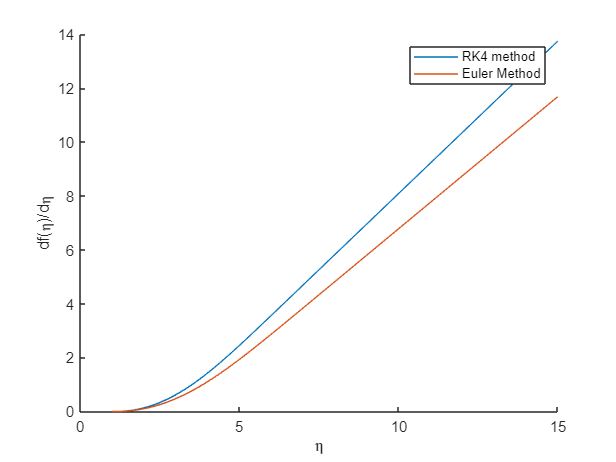

clc;
clear all;
prompt=input('Enter the first guess');
g1=prompt;                        %Getting two wild guesses from users
prompt=input('Enter the second guess');
g2=prompt;
prompt=input('Enter the length of the plate in units');
length=prompt; %Characteristic Length of Plate

guess=[g1 g2];
guesse=guess;
D_size=15;
Eta=linspace(1,D_size,50);
delta=(D_size-1)/50;
f(1)=0;
g(1)=0;
fe(1)=0;
ge(1)=0;
x_nondim=[0.2 0.4 0.6 0.8];
x_dim=x_nondim*length;


for i=1:4
    for j=1:50
       y(j,i)=Eta(j)*((x_dim(i))^0.5); %Dimensional matrix for plotting u(y) vs y
    end
end

for i=1:2 
    h(1)=guess(i);
    he(1)=guess(i);
    for j=2:50 % Loop that calculates f',f'',f''' for the two wild guesses using RK4,Euler Method
        temp=f(j-1)*h(j-1)*-0.5;
        temp_e=fe(j-1)*he(j-1)*-0.5;
        value=rungekutta4consts(delta,temp); % RK 4 Method
        h(j)=h(j-1)+value;
        he(j)=he(j-1)+temp_e*delta;%Euler Method
        value1=rungekutta4consts(delta,h(j-1));
        g(j)=g(j-1)+value1;
        ge(j)=ge(j-1)+he(j-1)*delta;
        value2=rungekutta4consts(delta,g(j-1));
        f(j)=f(j-1)+value2;
        fe(j)=fe(j-1)+ge(j-1)*delta;
    end
    err=abs(1-g(50));
    err_e=abs(1-ge(50));
    if err<10e-07 && err_e<10e-07
        break;
    else
        g_50(i)=g(50);
        g11(i,:)=g;
        f=zeros(1,50);
        g=zeros(1,50);
        h=zeros(1,50);
        g_50e(i)=ge(50);
        fe=zeros(1,50);
        ge=zeros(1,50);
        he=zeros(1,50);
    end
    
end
i=1;
j=3;

while(err>10e-07)
    a=g_50(j-1)-1; % Newton Raphson Method for manipulation of the correct guess from the given two wild guesses
   
    b=guess(j-1)-guess(j-2);
    
    c=g_50(j-1)-g_50(j-2);
   
    guess(j)=guess(j-1)-(a*(b/c));
    
   
    h(1)=guess(j);
   
    for r=2:50 % Loop for finding f',f'',f''' for other guesses excluding initial two wild guess
        temp=f(r-1)*h(r-1)*-0.5;
        
        value=rungekutta4consts(delta,temp);
        h(r)=h(r-1)+value;
        
        value1=rungekutta4consts(delta,h(r-1));
        g(r)=g(r-1)+value1;
        
        value2=rungekutta4consts(delta,g(r-1));
        f(r)=f(r-1)+value2;
        
    end
    err=abs(1-g(50));
    g_50(j)=g(50);
    g11(j,:)=g;
    
    j=j+1;
end


j=3;

while(err_e>10e-07)
     ae=g_50e(j-1)-1;
     be=guesse(j-1)-guesse(j-2);
     ce=g_50e(j-1)-g_50e(j-2);
     guesse(j)=guesse(j-1)-(ae*(be/ce));
     he(1)=guesse(j); 
     for r=2:50
         temp_e=fe(r-1)*he(r-1)*-0.5;
         he(r)=he(r-1)+temp_e*delta;
         ge(r)=ge(r-1)+he(r-1)*delta;
         fe(r)=fe(r-1)+ge(r-1)*delta;
     end
     err_e=abs(1-ge(50));
     g_50e(j)=ge(50);
     j=j+1;
end









figure(4);
hold on;
plot(Eta,f);
plot(Eta,fe);
xlabel('\eta');
ylabel('df(\eta)/d\eta');
legend('RK4 method','Euler Method');
hold off;

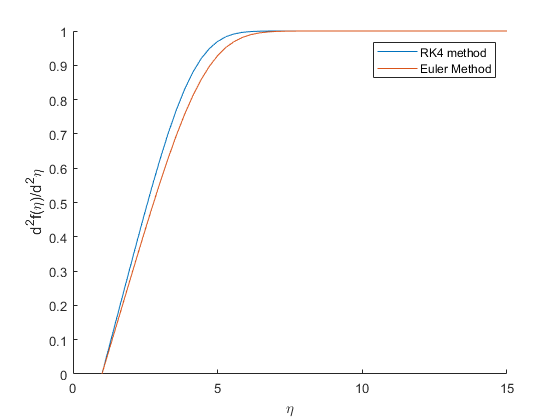

figure(5);
hold on;
plot(Eta,g);
plot(Eta,ge);
xlabel('\eta');
ylabel('d^2f(\eta)/d^2\eta');
legend('RK4 method','Euler Method');
hold off;

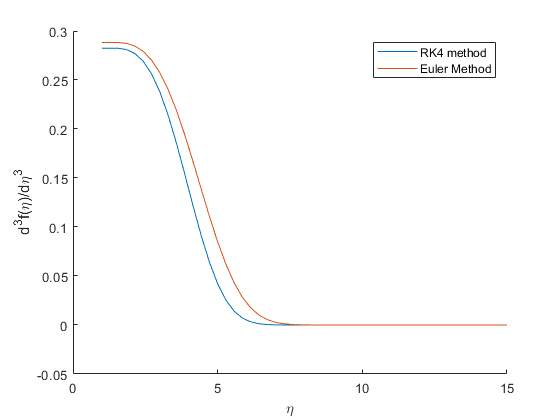

figure(6);
hold on;
plot(Eta,h);
plot(Eta,he);
xlabel('\eta');
ylabel('d^3f(\eta)/d\eta^3');
legend('RK4 method','Euler Method');
hold off;

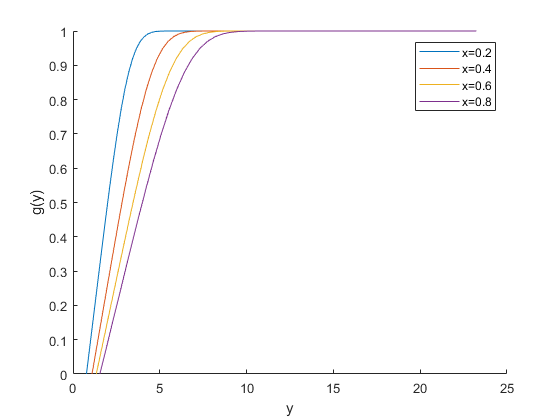

figure(7);
hold on;
plot(y(:,1),transpose(g));
plot(y(:,2),transpose(g));
plot(y(:,3),transpose(g));
plot(y(:,4),transpose(g));
legend('x=0.2','x=0.4','x=0.6','x=0.8');
xlabel('y');
ylabel('g(y)');
hold off;

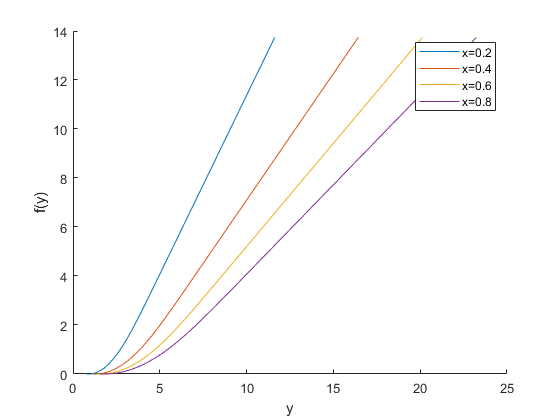

figure(8);
hold on;
plot(y(:,1),transpose(f));
plot(y(:,2),transpose(f));
plot(y(:,3),transpose(f));
plot(y(:,4),transpose(f));
legend('x=0.2','x=0.4','x=0.6','x=0.8');
xlabel('y');
ylabel('f(y)');
hold off;

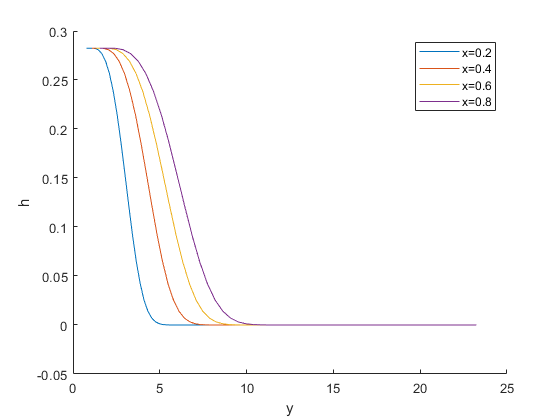

figure(9);
hold on;
plot(y(:,1),transpose(h));
plot(y(:,2),transpose(h));
plot(y(:,3),transpose(h));
plot(y(:,4),transpose(h));
legend('x=0.2','x=0.4','x=0.6','x=0.8');
xlabel('y');
ylabel('h');
hold off;

function [val]=rungekutta4consts(del,g_int)% Function for calculating RK4 constants
k1=del*g_int;
k2=del*(g_int+0.5*k1);
k3=del*(g_int+0.5*k2);
k4=del*(g_int+k3);
val=(k1+2*k2+2*k3+k4)/6;
end